clc; clear all; close all;

K=5; 
T=4; 

c=1; %Capacitancia 1=100%

% %% ITAE (integral time absulote error) optimal Tuning Method
% % Tavakoli, Saeed, and Mahdi Tavakoli. "Optimal tuning of PID controllers 
% % for first order plus time delay models using dimensional analysis." 2003 
% % 4th International Conference on Control and Automation Proceedings. 
% % IEEE, 2003.
% Kdc=1;
% td=0; % Time delay
% Kc=(1/K)*0.8/(td/T+0.1);
% Ti=(0.3*td+T);
% Td=td*(0.06/((td/T)+0.04))
% 
% %% Configuring MRAC control system for fractioanl order model
% % Adaptation rate
% Gamma=-abs(Kc/Ti); 
% Closed Loop Transfer Function Model (Modelo de referencia dado)
% dp=td; % Apperent Delay

DenPlant=[T 1]; %Denominador polynomial
NumPlant=[K];%Numerador polynomial
Gm1=tf(NumPlant,DenPlant)

Gm1 =
 
     5
  -------
  4 s + 1
 
Continuous-time transfer function.




step(Gm1)
stepinfo(Gm1)

ans = struct with fields:
         RiseTime: 8.7880
    TransientTime: 15.6483
     SettlingTime: 15.6483
      SettlingMin: 4.5225
      SettlingMax: 4.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 4.9999
         PeakTime: 42.1834



Os=0.1;
Ts=1;
Ps=0.02;

zeta=-log(Os)/sqrt(pi^2 + log(Os)^2);
wn=-log(Ps)/(zeta*Ts);

zeta=ceil(zeta*100)/100;
wn=ceil(wn);

p1=(-zeta+sqrt(zeta^2 -1))*wn

p1 = -4.2000 + 5.6000i

p2=(-zeta-sqrt(zeta^2 -1))*wn

p2 = -4.2000 - 5.6000i


s=tf('s');
pd=(s-p1)*(s-p2)

pd =
 
  s^2 + 8.4 s + 49
 
Continuous-time transfer function.



Gm2=tf(49, [1 8.4 49])

Gm2 =
 
         49
  ----------------
  s^2 + 8.4 s + 49
 
Continuous-time transfer function.



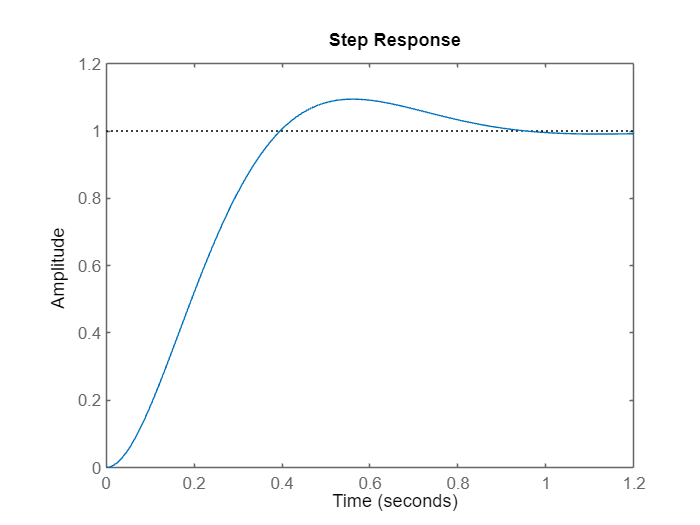

step(Gm2)

stepinfo(Gm2)

ans = struct with fields:
         RiseTime: 0.2651
    TransientTime: 0.8491
     SettlingTime: 0.8491
      SettlingMin: 0.9083
      SettlingMax: 1.0948
        Overshoot: 9.4773
       Undershoot: 0
             Peak: 1.0948
         PeakTime: 0.5592



stepinfo(out.Yp1.Data,out.Yp1.Time)
stepinfo(out.Yp2.Data,out.Yp2.Time)

ans = struct with fields:
         RiseTime: 0.2633
    TransientTime: 40.8747
     SettlingTime: 40.8747
      SettlingMin: 45.1403
      SettlingMax: 55.1558
        Overshoot: 10.3724
       Undershoot: 0
             Peak: 55.1558
         PeakTime: 40.5649
